## Numerical Integration - Chapter 19

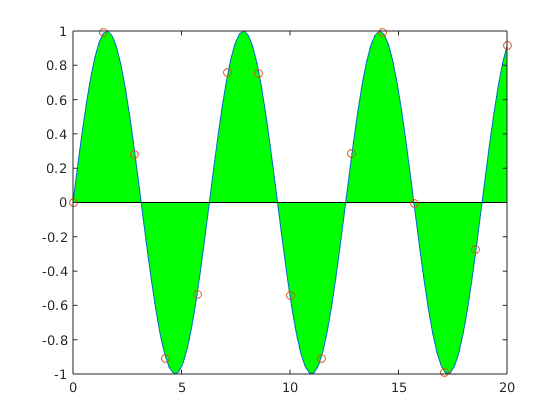

fcn = @(x) sin(x);

n = 15;
x = linspace(0, 20, n);
xx = linspace(0, 20, 100);


fill([xx(1), xx, xx(end)], ...
    [0, fcn(xx), 0], 'g')
hold on
plot(xx, fcn(xx), '-')
plot(x, fcn(x), 'o')

### Trapezoidal Rule

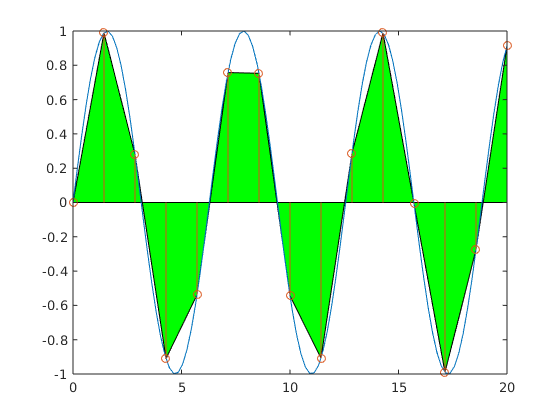

cla
fill([x(1), x, x(end)], ...
    [0, fcn(x), 0], 'g')
hold on
plot(xx, fcn(xx), '-')
stem(x, fcn(x), 'o')

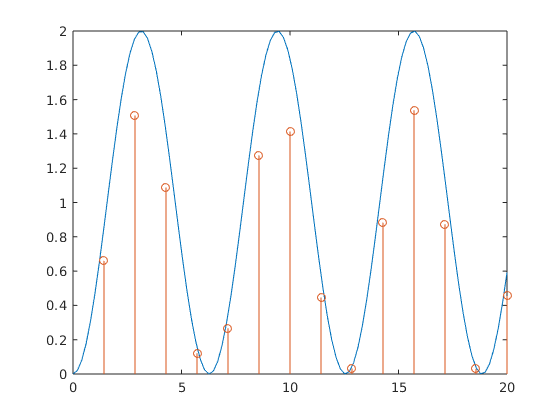


y = fcn(x);
avg = .5*(y(1:end-1)+y(2:end));

int_trapz = (x(end)-x(1))/(n) * cumsum(avg);

figure
exact_integral = @(x) 1-cos(x);
plot(xx, exact_integral(xx))
hold on
stem(x(2:end), int_trapz)

### Simpson's 1/3 rule

num = y(1) + 4*sum(y(2:2:end-1)) + ...
    2*sum(y(3:2:end-2)) + y(end);

int_simpson13 = 1/3*(x(end)-x(1))/(n) * num

int_simpson13 = 0.5692

int_trapezoidal = int_trapz(end)

int_trapezoidal = 0.4551

int_exact = exact_integral(x(end))

int_exact = 0.5919